%% QPSK Modulation with Rayleigh Noise Addition and Removal in Audio
% Wireless Standard: IEEE 802.11a | Pathway with Noise and Filtering
% Includes BER Calculation and Receiver Sensitivity Adjustment

%% Load the Original Audio File
[audioIn, fs] = audioread('input_voice.wav');  % Load input audio
audioIn = audioIn(:, 1);  % Use one channel if stereo
audioIn = audioIn / max(abs(audioIn));  % Normalize input

disp('Playing Original Audio...');

Playing Original Audio...


sound(audioIn, fs);
pause(length(audioIn)/fs + 1);

%% QPSK Modulation
scaledSignal = uint8((audioIn + 1) * 127);
bits = reshape(de2bi(scaledSignal, 8, 'left-msb')', [], 1);

M = 4;  % QPSK modulation order
padLength = mod(-length(bits), log2(M));
if padLength > 0
    bits = [bits; zeros(padLength, 1)];
end

symbols = bi2de(reshape(bits, log2(M), [])', 'left-msb');
modulatedSignal = pskmod(symbols, M, pi/4);
modulatedSignal = modulatedSignal / max(abs(modulatedSignal)); % Normalize

%% Add Rayleigh Noise and Adjust Receiver Sensitivity
noiseScale = 0.4;  % Noise scale for Rayleigh fading
rayleighNoise = raylrnd(noiseScale, size(modulatedSignal));
complexNoise = rayleighNoise .* exp(1j * 2 * pi * rand(size(modulatedSignal)));

signalPower = mean(abs(modulatedSignal).^2);
noisePower = mean(abs(complexNoise).^2);

desiredSNR_dB = 15;  % Desired SNR (Signal-to-Noise Ratio)
desiredSNR_linear = 10^(desiredSNR_dB / 10);
scaleFactor = sqrt(signalPower / (noisePower * desiredSNR_linear));

sensitivityGain = 2; % Receiver sensitivity adjustment
scaledNoise = complexNoise * scaleFactor * sensitivityGain;

noisySignal = modulatedSignal + scaledNoise;
noisySignal = noisySignal / max(abs(noisySignal)); % Normalize

%% QPSK Demodulation
receivedSymbols = pskdemod(noisySignal, M, pi/4);
receivedBits = reshape(de2bi(receivedSymbols, log2(M), 'left-msb')', [], 1);

expectedBits = length(audioIn) * 8;
receivedBits = receivedBits(1:expectedBits);
receivedBytes = reshape(receivedBits, 8, [])';
receivedInts = bi2de(receivedBytes, 'left-msb');
audioNoisy = (double(receivedInts) / 127) - 1;
audioNoisy = audioNoisy / max(abs(audioNoisy));  % Normalize

%% Bit Error Rate (BER) Calculation
BER = sum(bits ~= receivedBits) / length(bits);
fprintf('Bit Error Rate (BER): %.6f\n', BER);

Bit Error Rate (BER): 0.002490



disp('Playing Noisy Audio (QPSK with Rayleigh Noise)...');

Playing Noisy Audio (QPSK with Rayleigh Noise)...


sound(audioNoisy, fs);
pause(length(audioNoisy)/fs + 1);

%% Noise Removal Using Low-Pass Filtering
fc = 4000;  % Lower cut-off frequency
Wn = fc / (fs / 2);
[b, a] = butter(6, Wn, 'low');

audioFiltered = filter(b, a, audioNoisy);
audioFiltered = audioFiltered / max(abs(audioFiltered));  % Normalize

disp('Playing Denoised Audio...');

Playing Denoised Audio...


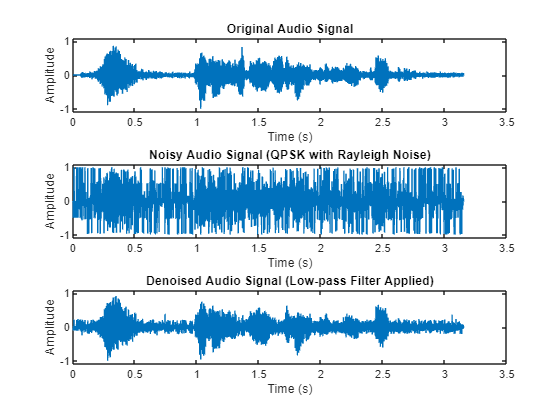

sound(audioFiltered, fs);
pause(length(audioFiltered)/fs + 1);

%% Plot Signal Comparisons
t = (0:length(audioIn)-1) / fs;  % Time vector

figure;
subplot(3,1,1);
plot(t, audioIn);
title('Original Audio Signal');
xlabel('Time (s)'); ylabel('Amplitude'); ylim([-1.1 1.1]);

subplot(3,1,2);
plot(t, audioNoisy);
title('Noisy Audio Signal (QPSK with Rayleigh Noise)');
xlabel('Time (s)'); ylabel('Amplitude'); ylim([-1.1 1.1]);

subplot(3,1,3);
plot(t, audioFiltered);
title('Denoised Audio Signal (Low-pass Filter Applied)');
xlabel('Time (s)'); ylabel('Amplitude'); ylim([-1.1 1.1]);


%% Save Processed Audio Files
audiowrite('noisy_audio.wav', audioNoisy, fs);
audiowrite('denoised_audio.wav', audioFiltered, fs);

%% Debug and Summary Information
fprintf('Original Signal Length: %d\n', length(audioIn));

Original Signal Length: 151200


fprintf('SNR (dB): %.2f\n', desiredSNR_dB);

SNR (dB): 15.00


fprintf('Noise Scale: %.2f\n', noiseScale);

Noise Scale: 0.40


fprintf('Receiver Sensitivity Gain: %.2f\n', sensitivityGain);

Receiver Sensitivity Gain: 2.00



disp('Audio Processing Complete. Files Saved.');

Audio Processing Complete. Files Saved.
